# Pole Placement Control: Stability

## System Data

clear 
close all
close all

% data for simscape model
% Run this block to initialise simscape pendulum model parameters

% Initial pendulum intial angle in degrees
% 180 corresponds to upright position
% can also be selected in the simulink model
alpha_0=170;

parametri = 1;      % 0 = nominali; 1 = identificati

%% System parameters
if parametri == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
else
    % Valori identificati
    load("th_id.mat")
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
end

voltage_max = 10;
theta_max = 45;     % Maximum theta rotation[deg]
alpha_max = 15;     % Maximum alpha deflection [deg]



## System State Space representation around the unstable equilibrium

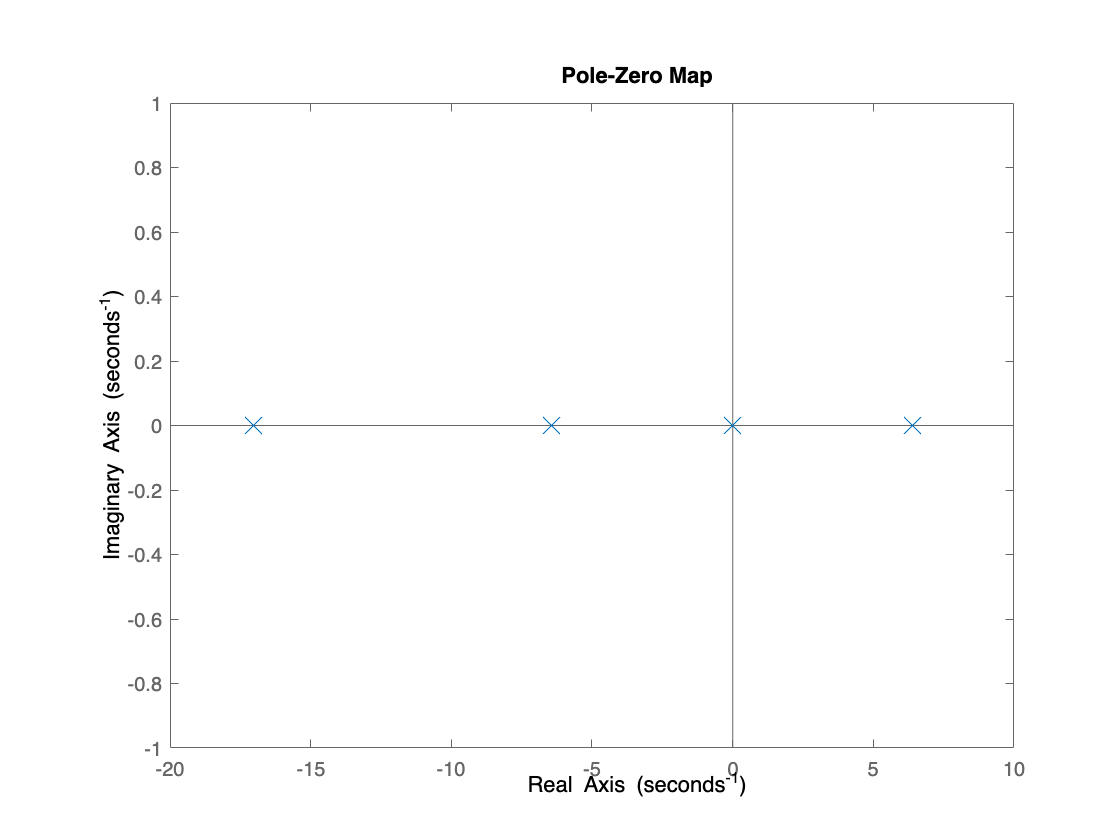

poli =          0
    6.4075
   -6.4233
  -17.0228


% [A,B,C,D] = SS_Matrices_Voltage_Unstable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
% C_full = eye(4);
% D_full = zeros(4,1);

[A,B,C,D] = SS_Matrices_Voltage_Unstable_Disturbance(B_p,B_r,J_T,J_a,J_p,K_g,L_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
B_d = B(:,2); % disturbance matrix
B_u = B(:,1); % input matrix
C_full = eye(4);
D_full = zeros(4,size(B,2));
D_full_u = D_full(:,1);

sys_ol = ss(A,B,C_full,D_full); % open loop system


figure(1);
pzmap(sys_ol)
set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);

We can see the presence of:

- An unstable real pole

- A zero at the origin

poli = pole(sys_ol)


zeri =

  0×1 empty double column vector



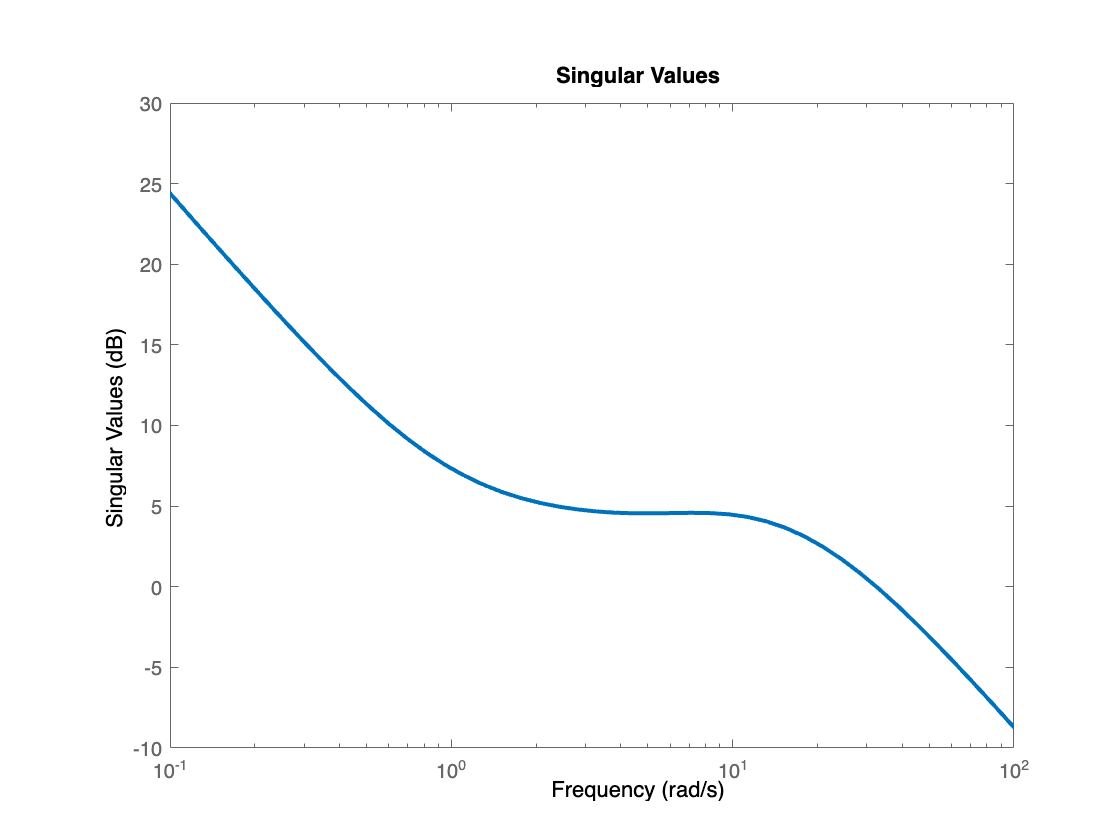

zeri = tzero(sys_ol)
figure(2);
sigma(sys_ol); % this command is needed to plot singular values

set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

## Pole Placement Controller Design

We want first to design a pole placement controller able to stabilize the pendulum around the vertical position.

Wr'll assume that the full state is measurable.

% Compute the reachability matrix for the pair (A, B)
n = size(A,1); % order of the system 
m = size(B_u,2); % input dimension
p = size(C,1); % measured_output dimension

M_r = ctrb(A, B_u); % this function computes the reachabiltiy matrix of the system

ans = logical
   1


rank(M_r) == n % we compute the rank of Mr and compare it to the order of the system -> number of states

### Chosing the poles positions

We stabilize the system and make it behave as a 2nd order system with a cutoff frequency of 5rad/s almost.

% pp_desired_poles = [-5 -5.1 -15 -15.1];
% pp_desired_poles = [-6-9i -6+9i -7 -7.001];
pp_desired_poles = [-8.4-12i -8.4+12i -11 -11.001];

Kpp =   -22.4860   56.6991   -6.6980    8.0272


Kpp = place(A, B_u, pp_desired_poles)

We then want to compare the singular values of the stabilized loop with the open loop ones:

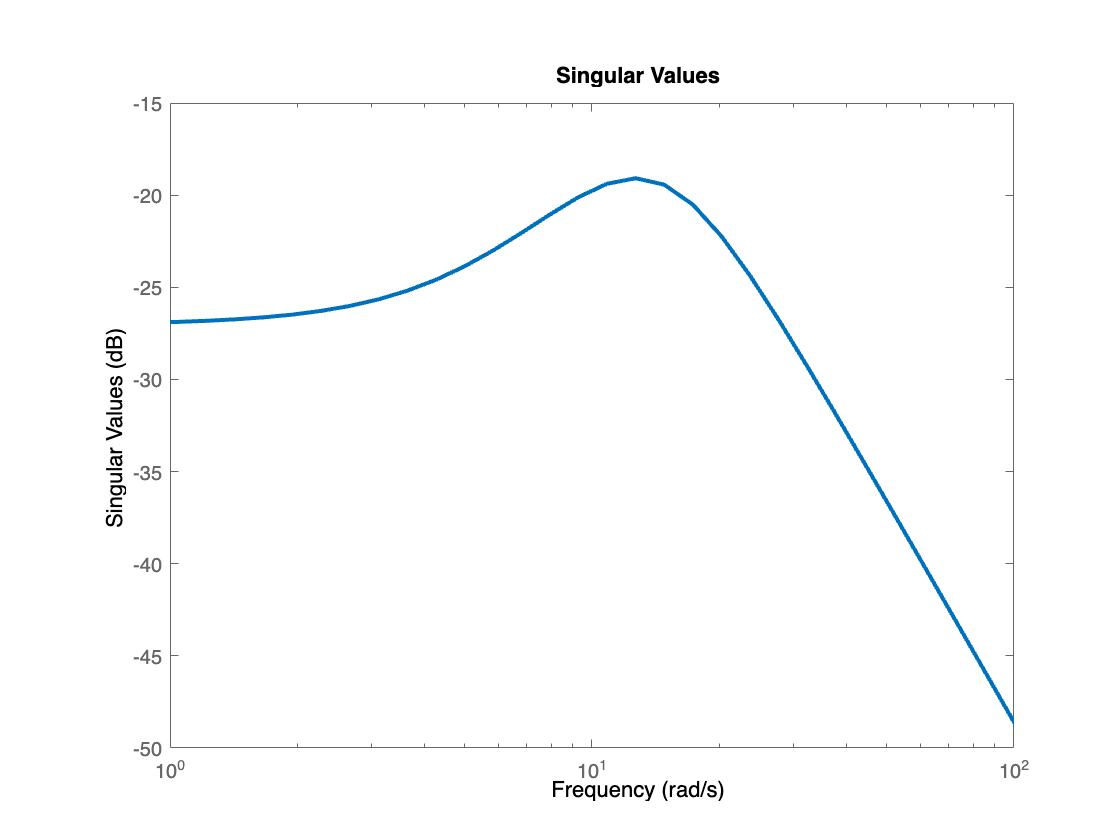

sys_cl_pp = ss(A - B_u * Kpp, B_u, C, D); % we define a ss representation

figure(3);
sigma(sys_cl_pp); % we compute eigs

set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

% Compute the osservability matrix
M_o = obsv(A, C);

ans = logical
   1


rank(M_o) == n
% obsv_poles = [-40,-40.1, -55+50i, -55-50i];
% obsv_poles = [-40,-40.1,-50-10i,-50+10i];
obsv_poles = [-40-4i,-40+4i,-50-5i,-50+5i];
% obsv_poles = [-40,-40.1,-50,-50.1];

L_obs = 1.0e+03 *

    0.0730   -0.0015
   -0.0158    0.0900
    0.8119   -0.0111
   -1.2200    2.0502


Introducing complex conjugate poles allowed to reduce the inverse response of the observer.

L_obs = place(A', C', obsv_poles)'
A_ob = A - L_obs*C;
B_ob = [B_u - L_obs*D, L_obs];
C_ob = eye(n);
D_ob = zeros(n, m+p);


We can look at the poles and zeros of the observer to understand why we have an inverse response when estimating the speed $\dot{\alpha}$:

sys_obs = ss(A_ob,B_ob,C_ob,D_ob);

obs_poles =  -50.0000 + 5.0000i
 -50.0000 - 5.0000i
 -40.0000 + 4.0000i
 -40.0000 - 4.0000i


obs_poles = pole(sys_obs)


obs_zeros =

  0×1 empty double column vector



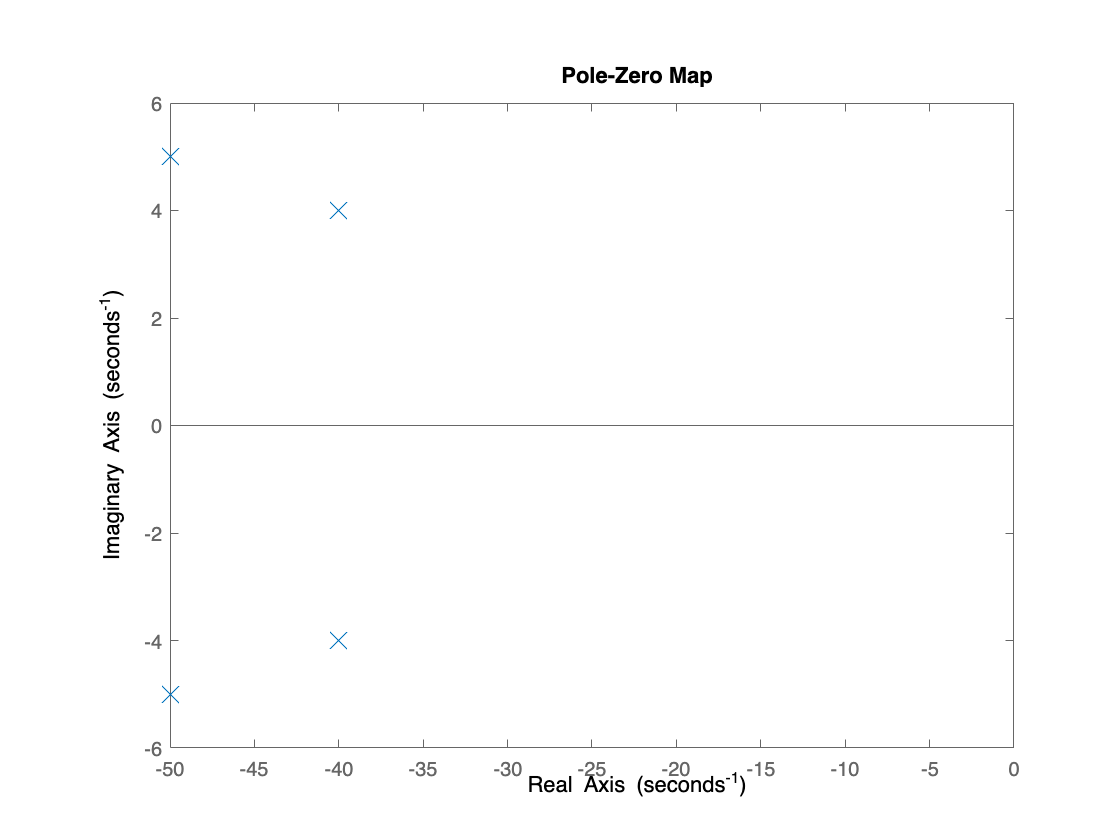

obs_zeros = tzero(sys_ol)

figure(4);
pzmap(sys_obs)

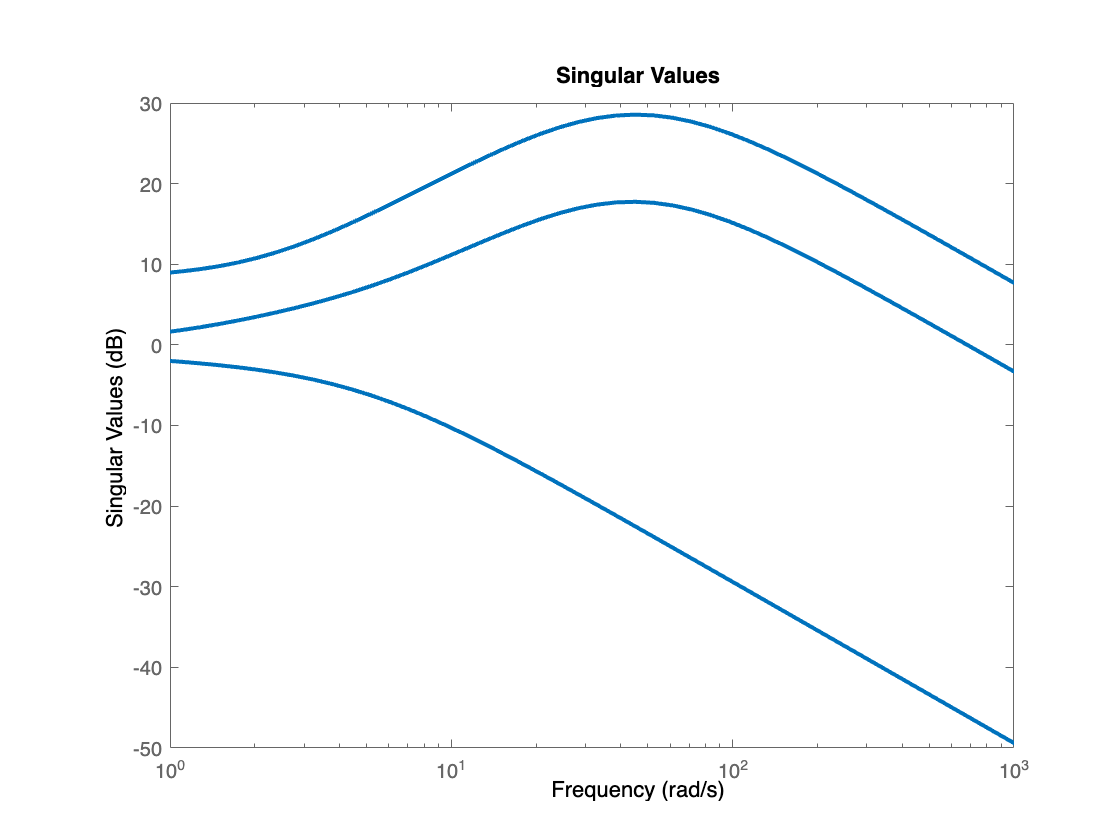

set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);
figure(5);
sigma(sys_obs); % we compute eigs

set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

x0 = [0;0.26;0;0]; % initial state for simulation alpha range in +/- 0.26 rad
% x0 = [0;0.09;0;0];

% FOR CAD MODEL:
% DC Motor Parameters
% kt=k_t;% torque constant
% km=k_m;% motor back-emf constant
% R = R_m;% terminal resistance
% L = 0.18e-3;% terminal inductance
% 
% % Inverted Pendulum Parameters
% % lengths are in cm and mass in kg
% base_size=7; % length of pendulum base cube
% % Rotary arm parameters
% rod_rad=1;% rotary arm radius
% rod_length=21.6;% rotary arm length
% rod_mass=0.257;% rotary arm mass
% % Pendulum parameters
% p_rad=1;% pendulum radius
% p_length=33.7;% pendulum length
% p_mass=m_p;% pendulum mass
% rt1=base_size/2;
% rt2=rod_length-0.4;
% rt4=p_length/2;
% D_r=B_r;
% D_p=B_p;
